# Final Project Writeup

## Behavioral: Curvature Metric

Behavioral: Find a curvature metric (ratio of actual path length to straight line distance between start and end). Plot the distribution of curvature with a bootstrapped confidence interval for curved and straight path conditions. This would be a behavioral verification that the animal actually did the curved paths and not just the straight length ones. 

num_trials = length(R);
num_directions = 36;
mazeCategory = {R.mazeCategory};
moveOnsetTimes = [R.moveOnsetTime];
moveEndsTimes = [R.moveEndsTime];
targetXYs = {R.targetXY};
fixationXYs = {R.fixationXY};

conditionIDs = [R.conditionID];
straight_idx = mod(conditionIDs, 3) == 1;
curved_idx   = mod(conditionIDs, 3) == 2;

curvature = nan(1, num_trials);

for trial = 1:num_trials
    hand_times = R(trial).HAND.times;
    x_pos = R(trial).HAND.X;
    y_pos = R(trial).HAND.Y;

    [~, moveOnsetTime_idx] = min(abs(hand_times - moveOnsetTimes(trial)));
    [~, moveEndsTime_idx]   = min(abs(hand_times - moveEndsTimes(trial)));

    x_segment = x_pos(moveOnsetTime_idx:moveEndsTime_idx);
    y_segment = y_pos(moveOnsetTime_idx:moveEndsTime_idx);

    coordinates = [x_segment(:), y_segment(:)];
    segment_lengths = sqrt(sum(diff(coordinates).^2, 2));
    total_path_length = sum(segment_lengths);
    straight_line_dist = sqrt((x_segment(end) - x_segment(1))^2 + (y_segment(end) - y_segment(1))^2);
    curvature(trial) = total_path_length / straight_line_dist;
end

straight_curv = curvature(straight_idx & ~isnan(curvature));
curved_curv = curvature(curved_idx & ~isnan(curvature));

figure;
subplot(1,2,1);
histogram(straight_curv, 30, 'FaceColor', [0 0 0.8], 'EdgeColor', 'none', 'Normalization', 'probability');
hold on;
xlabel('Curvature Ratio');
ylabel('Proportion of Trials');
title('No Barriers');
xlim([0.5 3]);

subplot(1,2,2);
histogram(curved_curv, 30, 'FaceColor', 'red', 'EdgeColor', 'none', 'Normalization', 'probability');
hold on;
xlabel('Curvature Ratio');
ylabel('Proportion of Trials');
title('Barriers');
xlim([0.5 3]);

sgtitle('Path Curvature Distribution by Condition');

% Bootstrap 
n_bootstrap = 10000;
straight_random_inds = randi(numel(straight_curv), numel(straight_curv), n_bootstrap);
straight_bootstrap = mean(straight_curv(straight_random_inds), 1);

curved_random_inds = randi(numel(curved_curv), numel(curved_curv), n_bootstrap);
curved_bootstrap = mean(curved_curv(curved_random_inds), 1);

straight_mean = mean(straight_curv);
straight_ci = prctile(straight_bootstrap, [2.5, 97.5]);

curved_mean = mean(curved_curv);
curved_ci = prctile(curved_bootstrap, [2.5, 97.5]);

figure;
hold on;

histogram(straight_bootstrap, 50, 'FaceColor', [0 0 0.8], 'FaceAlpha', 0.5, 'EdgeColor', 'none', 'Normalization', 'probability');
histogram(curved_bootstrap, 50, 'FaceColor', 'red', 'FaceAlpha', 0.5, 'EdgeColor', 'none', 'Normalization', 'probability');

yl = ylim;
fill([straight_ci(1) straight_ci(2) straight_ci(2) straight_ci(1)], ...
     [0 0 yl(2) yl(2)], [0 0 0.8], 'FaceAlpha', 0.15, 'EdgeColor', 'none');
fill([curved_ci(1) curved_ci(2) curved_ci(2) curved_ci(1)], ...
     [0 0 yl(2) yl(2)], 'red', 'FaceAlpha', 0.15, 'EdgeColor', 'none');

xline(straight_mean, 'b-', 'LineWidth', 2);
xline(curved_mean, 'r-', 'LineWidth', 2);

legend('No Barriers bootstrap', 'Barriers bootstrap', ...
       'No Barriers 95% CI', 'Barriers 95% CI', ...
       'No Barriers mean', 'Barriers mean', ...
       'Location', 'best');
xlabel('Mean Curvature Ratio');
ylabel('Proportion of Bootstrap Samples');
title('Bootstrap Mean Distributions with 95% CIs');


## Behavioral: Peak Hand Velocity

Behavioral: Hand velocity over time split by the curved and straight reaches. Compute peak hand speed during trial, split trials into groups based on curved or straight reaches, compare the means. 

Monte Carlo: shuffle the curved/straight labels, recompute the difference in the means, do this 1,000 times to create a null distribution. P-value would show us if curved and straight reaches have significantly different peak hand speeds. 

% Find peak speeds
num_trials = length(R);
moveOnsetTimes = [R.moveOnsetTime];
moveEndsTimes = [R.moveEndsTime];

conditionIDs = [R.conditionID];
straight_idx = mod(conditionIDs, 3) == 1;
curved_idx   = mod(conditionIDs, 3) == 2;

peak_speeds = nan(1, num_trials);

for trial = 1:num_trials
    hand_times = R(trial).HAND.times(:);
    x_pos = R(trial).HAND.X(:);
    y_pos = R(trial).HAND.Y(:);

    [~, moveOnsetTimes_idx] = min(abs(hand_times - moveOnsetTimes(trial)));
    [~, moveEndsTimes_idx]  = min(abs(hand_times - moveEndsTimes(trial)));

    x_seg = x_pos(moveOnsetTimes_idx:moveEndsTimes_idx);
    y_seg = y_pos(moveOnsetTimes_idx:moveEndsTimes_idx);

    dt = diff(hand_times(moveOnsetTimes_idx:moveEndsTimes_idx));
    dx = diff(x_seg);
    dy = diff(y_seg);

    valid = dt > 0;
    dt = dt(valid);
    dx = dx(valid);
    dy = dy(valid);

    speed = sqrt((dx ./ dt).^2 + (dy ./ dt).^2);
    peak_speeds(trial) = max(speed);
end

straight_speed = peak_speeds(straight_idx & ~isnan(peak_speeds));
curved_speed = peak_speeds(curved_idx   & ~isnan(peak_speeds));
observed_diff = mean(curved_speed) - mean(straight_speed);

figure;
subplot(1,2,1);
histogram(straight_speed, 30, 'FaceColor', [0 0 0.8], 'EdgeColor', 'none', 'Normalization', 'probability');
hold on;
xline(mean(straight_speed), 'b--', 'LineWidth', 2);
xlabel('Peak Hand Speed');
ylabel('Proportion of Trials');
title('No Barriers');

subplot(1,2,2);
histogram(curved_speed, 30, 'FaceColor', 'red', 'EdgeColor', 'none', 'Normalization', 'probability');
hold on;
xline(mean(curved_speed), 'r--', 'LineWidth', 2);
xlabel('Peak Hand Speed');
ylabel('Proportion of Trials');
title('Barriers');

sgtitle('Peak Hand Speed Distribution by Condition');

% Monte Carlo 
n_perm = 10000;
permutation_diffs = nan(1, n_perm);
pooled_speeds = [straight_speed, curved_speed];
num_straight_speeds = numel(straight_speed);

for i = 1:n_perm
    shuffled = pooled_speeds(randperm(numel(pooled_speeds)));
    perm_straight = shuffled(1:num_straight_speeds);
    perm_curved = shuffled(num_straight_speeds+1:end);
    permutation_diffs(i) = mean(perm_curved) - mean(perm_straight);
end

p_value = mean(abs(permutation_diffs) >= abs(observed_diff));

% Plotting
figure;
histogram(permutation_diffs, 50, 'FaceColor', [0.5 0.5 0.5], 'EdgeColor', 'none', 'Normalization', 'probability');
hold on

xline(observed_diff, 'r--', 'LineWidth', 2);
xline(-observed_diff, 'r--', 'LineWidth', 2);

xlabel('Difference in Mean Peak Speed (Curved - Straight)');
ylabel('Proportion of Permutations');
title(sprintf('Null Distribution (Monte Carlo Permutation Test)\nObserved difference = %.3f, p = %.3f', observed_diff, p_value));
legend('Null distribution', 'Observed difference');

## Trial by Trial Variability

We will compute the Fano Factor as a function of time aligned to both the target appearance, movement onset, and go-cue separately for curved and straight reaches to determine how variability evolves across delay and movement and whether this differs for the reach types, considering curved reaches are arguably more complex.

% We will compute the Fano Factor as a function of time aligned to both the 
% target appearance, movement onset, and go-cue separately for curved and straight 
% reaches to determine how variability evolves across delay and movement 
% and whether this differs for the reach types, considering curved reaches 
% are arguably more complex.

conditionIDs = [R.conditionID];
straight_idx = mod(conditionIDs, 3) == 1;
curved_idx = mod(conditionIDs, 3) == 2;

straight_trials = find(straight_idx);
curved_trials   = find(curved_idx);

bin_size = 50;
step_size = 10;
pre_window = 400;
post_window = 600;

bin_centers = (-pre_window + bin_size/2) : step_size : (post_window - bin_size/2);
num_bins = numel(bin_centers);
num_units = numel(R(1).unit);

target_align = [R.targetAppearsTime];
gocue_align = [R.goCueTime];
onset_align = [R.moveOnsetTime];

straight_dir_ids = floor(conditionIDs(straight_idx) / 3); 
curved_dir_ids = floor(conditionIDs(curved_idx) / 3);

unique_straight_dirs = unique(straight_dir_ids);
unique_curved_dirs = unique(curved_dir_ids);

ff_target = nan(num_units, num_bins, 2);
ff_gocue = nan(num_units, num_bins, 2);
ff_onset = nan(num_units, num_bins, 2);

for unit = 1:num_units
    for cond = 1:2
        if cond == 1
            trial_ids = straight_trials;
            dir_ids = straight_dir_ids;
            unique_dirs = unique_straight_dirs;
        else
            trial_ids = curved_trials;
            dir_ids = curved_dir_ids;
            unique_dirs = unique_curved_dirs;
        end

        num_dirs = numel(unique_dirs);

        ff_target_by_dir = nan(num_dirs, num_bins);
        ff_gocue_by_dir = nan(num_dirs, num_bins);
        ff_onset_by_dir = nan(num_dirs, num_bins);

        for d = 1:num_dirs
            dir_mask = dir_ids == unique_dirs(d);
            dir_trial_ids = trial_ids(dir_mask); 
            num_dir_trials = numel(dir_trial_ids);

            counts_target = nan(num_dir_trials, num_bins);
            counts_gocue = nan(num_dir_trials, num_bins);
            counts_onset = nan(num_dir_trials, num_bins);

            for trial = 1:num_dir_trials
                tr = dir_trial_ids(trial);
                spike_times = R(tr).unit(unit).spikeTimes;

                rel_target = spike_times - target_align(tr);
                rel_gocue = spike_times - gocue_align(tr);
                rel_onset = spike_times - onset_align(tr);

                for b = 1:num_bins
                    t_lo = bin_centers(b) - bin_size/2;
                    t_hi = bin_centers(b) + bin_size/2;

                    counts_target(trial, b) = sum(rel_target >= t_lo & rel_target < t_hi);
                    counts_gocue( trial, b) = sum(rel_gocue  >= t_lo & rel_gocue  < t_hi);
                    counts_onset( trial, b) = sum(rel_onset  >= t_lo & rel_onset  < t_hi);
                end
            end

            ff_target_by_dir(d, :) = compute_fano_factor(counts_target);
            ff_gocue_by_dir( d, :) = compute_fano_factor(counts_gocue);
            ff_onset_by_dir( d, :) = compute_fano_factor(counts_onset);
        end

        ff_target(unit, :, cond) = nanmean(ff_target_by_dir, 1);
        ff_gocue( unit, :, cond) = nanmean(ff_gocue_by_dir,  1);
        ff_onset( unit, :, cond) = nanmean(ff_onset_by_dir,  1);
    end
end

mean_ff = @(ff, cond) nanmean(ff(:, :, cond), 1);
sem_ff = @(ff, cond) nanstd(ff(:, :, cond), 0, 1) / sqrt(sum(~all(isnan(ff(:,:,cond)), 2)));

%Plotting
colors = struct('straight', [0 0 0.8], 'curved', [0.8 0 0]);
align_labels = {'Target Appearance', 'Go Cue', 'Movement Onset'};
x_labels = {'Time from Target Appearance (ms)', ...
                 'Time from Go Cue (ms)', ...
                 'Time from Movement Onset (ms)'};
ff_all = {ff_target, ff_gocue, ff_onset};

figure;

for a = 1:3
    subplot(1, 3, a);
    hold on;
    ff = ff_all{a};
    for cond = 1:2
        m  = mean_ff(ff, cond);
        sem = sem_ff(ff, cond);
        if cond == 1
            col = colors.straight;
            lbl = 'Straight';
            fill_lbl = 'SEM Straight';
        else
            col = colors.curved;
            lbl = 'Curved';
            fill_lbl = 'SEM Curved';
        end
        fill([bin_centers, fliplr(bin_centers)], ...
             [m + sem, fliplr(m - sem)], ...
             col, 'FaceAlpha', 0.2, 'EdgeColor', 'none', 'DisplayName', fill_lbl);
        plot(bin_centers, m, '-', 'Color', col, 'LineWidth', 2, 'DisplayName', lbl);
    end
    xline(0, 'k--', 'LineWidth', 1.5, 'HandleVisibility', 'off');
    yline(1, 'k:',  'LineWidth', 1.0, 'HandleVisibility', 'off');

    xlabel(x_labels{a});
    ylabel('Fano Factor');
    title(align_labels{a});
    xlim([-pre_window, post_window]);
    if a == 1
        legend('Location', 'best');
    end
end
sgtitle('Population Fano Factor');


Method:

- Trials are split into straight vs curved

- Trials are grouped by reach direction (36 conditions as indicated by the dataset)

- Spike counts are binned in 50ms windows, stepped every 10ms. The window of interest is 400ms before to 600ms after each alignment event (target appearance, go cue, and movement onset)

- For each direction group, FF is computed per bin per unit, then averaged across directions, then averaged across all units

As we learned in class, the Fano Factor (FF) is used to quantify neural variability, with FF=1 indicating regular firing. The plot shown was averaged At target appearance, the variabilty drops, and steadily rises. The same pattern is shown in the go cue alignment plot. Interestingly, the curved reaches have a slightly higher variability throughout this plot, although the difference is minimal. This could be because the curved reaches are more complex than the straight reaches, and less stereotyped after instruction. Different curved trials may involve differeny movement strategies during this planning phase initiated by the go cue. It also might indicate that straight reaches are more stereotyped after the appearance of the go-cue. When aligned to the movement onset, we see the opposite pattern. The straight reaches have a higher variability after movement onset compared to the curved reaches. This could mean that at movement onset, the curved trajectories execute movement in a stereotyped way. These results suggest that straight reaches are more locked to instruction, and curved reaches are more locked to execution. However, it is important to note that these differences in variability are minor. In addition, averaging over the population might minimize the differences in variability we see between the two conditions. 

## NOTE: Put in FF between arrays and single units

## Linear Dimensionality Reduction

We will do cross-validated PCA on M1 activity to determine the true low dimensional structure of the neuron's responses, comparing dimensionality under no normalization, z-scoring, and soft normalization.

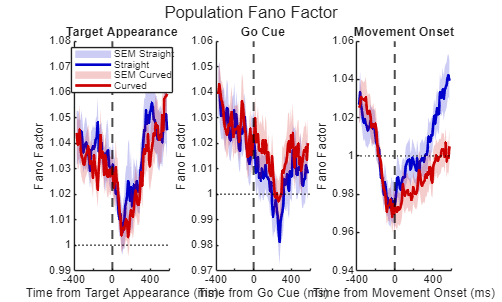

conditionIDs = [R.conditionID];
straight_idx = mod(conditionIDs, 3) == 1;
curved_idx = mod(conditionIDs, 3) == 2;
straight_trials = find(straight_idx);
curved_trials = find(curved_idx);

% window will change in the next PCA trajectory analysis this is just for
pre_window = 150;
post_window = 50;

bin_size = 20;
time_bins = -pre_window : bin_size : post_window;
bin_centers = time_bins(1:end-1) + bin_size/2;
n_bins = numel(bin_centers);
n_units = numel(R(1).unit);

onset_align = [R.moveOnsetTime];
all_trials = [straight_trials(:); curved_trials(:)];
n_trials = numel(all_trials);

firing_rates = nan(n_trials, n_units, n_bins);
for t = 1:n_trials
    tr = all_trials(t);
    t0 = onset_align(tr);
    for u = 1:n_units
        spike_times = R(tr).unit(u).spikeTimes - t0;
        counts = histcounts(spike_times, time_bins);
        firing_rates(t, u, :) = counts / (bin_size / 1000);
    end
end
disp('Firing rates created.')

fr_straight = squeeze(mean(firing_rates(1:numel(straight_trials), :, :), 1));  % [n_units x n_bins]
fr_curved   = squeeze(mean(firing_rates(numel(straight_trials)+1:end, :, :), 1));
fr_cond_avg = permute(cat(3, fr_straight', fr_curved'), [3 1 2]);  % [2 x n_bins x n_units]
n_conds = 2;

k = 5;
soft_norm = 5;
methods = {'none', 'zscore', 'soft'};
normalization_labels = {'No Normalization', 'Z-Score', 'Soft Normalization'};
colors_method = [0 0 0; 0 0 1; 1 0 0];

n_straight = numel(straight_trials);
n_curved = numel(curved_trials);
cond_labels = [ones(n_straight, 1); 2*ones(n_curved, 1)];

fold_ids_trials = zeros(n_trials, 1);

Firing rates created.


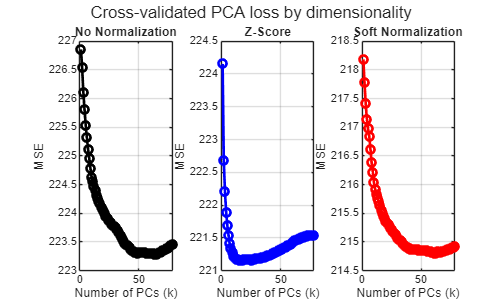

for cond = 1:2
    cond_mask = find(cond_labels == cond);
    n_cond = numel(cond_mask);
    perm = randperm(n_cond);
    cond_folds = mod(0:n_cond-1, k) + 1;
    fold_ids_trials(cond_mask) = cond_folds(perm);
end

n_X_fixed = floor(n_units / 2);
max_dims = n_X_fixed - 1;

cv_loss = nan(numel(methods), k, k, max_dims);
n_plot_dims = min(n_X_fixed - 1, 2*n_bins - 1);
all_explained = nan(numel(methods), n_plot_dims);
all_score = cell(numel(methods), 1);
all_coeff = cell(numel(methods), 1);

for m = 1:numel(methods)

    for fold_r = 1:k
        train_idx = find(fold_ids_trials ~= fold_r);
        test_idx = find(fold_ids_trials == fold_r);
        n_train = numel(train_idx);
        n_test = numel(test_idx);

        for fold_c = 1:k
            neuron_perm = randperm(n_units);
            x_neurons = neuron_perm(1:n_X_fixed);
            y_neurons = neuron_perm(n_X_fixed+1:end);
            n_Y = numel(y_neurons);

            X_train = reshape(permute(firing_rates(train_idx, x_neurons, :), [1 3 2]), n_train*n_bins, n_X_fixed);
            Y_train = reshape(permute(firing_rates(train_idx, y_neurons, :), [1 3 2]), n_train*n_bins, n_Y);
            X_test = reshape(permute(firing_rates(test_idx,  x_neurons, :), [1 3 2]), n_test*n_bins,  n_X_fixed);
            Y_test = reshape(permute(firing_rates(test_idx,  y_neurons, :), [1 3 2]), n_test*n_bins,  n_Y);

            switch methods{m}
                case 'none'
                    X_train_n = X_train; X_test_n = X_test;
                case 'zscore'
                    mu_x = mean(X_train, 1);
                    sig_x = std(X_train, 0, 1); sig_x(sig_x==0) = 1;
                    X_train_n = (X_train - mu_x) ./ sig_x;
                    X_test_n  = (X_test  - mu_x) ./ sig_x;
                case 'soft'
                    rng_x = max(X_train,[],1) - min(X_train,[],1);
                    X_train_n = X_train ./ (rng_x + soft_norm);
                    X_test_n  = X_test  ./ (rng_x + soft_norm);
            end

            mu_X = mean(X_train_n, 1);
            X_train_c = X_train_n - mu_X;
            X_test_c = X_test_n  - mu_X;
            mu_Y = mean(Y_train, 1);
            Y_train_c = Y_train - mu_Y;

            [coeff, score, ~] = pca(X_train_c, 'NumComponents', max_dims);

            for d = 1:max_dims
                S_train = score(:, 1:d);
                beta = S_train \ Y_train_c;
                S_test = X_test_c * coeff(:, 1:d);
                Y_hat = S_test * beta + mu_Y;
                cv_loss(m, fold_r, fold_c, d) = mean((Y_test - Y_hat).^2, 'all');
            end
        end
    end

    X_plot = reshape(fr_cond_avg(:, :, :), n_conds*n_bins, n_units);
    FR_all = reshape(permute(firing_rates, [1 3 2]), n_trials*n_bins, n_units);
    
    switch methods{m}
        case 'none'
            FR_all_n = FR_all;
        case 'zscore'
            mu_x = mean(FR_all, 1);
            sig_x = std(FR_all, 0, 1); sig_x(sig_x==0) = 1;
            FR_all_n = (FR_all - mu_x) ./ sig_x;
        case 'soft'
            rng_x = max(FR_all,[],1) - min(FR_all,[],1);
            FR_all_n = FR_all ./ (rng_x + soft_norm);
    end
    
    FR_all_n = reshape(FR_all_n, n_trials, n_bins, n_units);
    psth_s = squeeze(mean(FR_all_n(1:n_straight, :, :), 1)); 
    psth_c = squeeze(mean(FR_all_n(n_straight+1:end, :, :), 1));
    X_plot_final = [psth_s; psth_c];
    X_plot_final = X_plot_final - mean(X_plot_final, 1);
    
    [coeff_full, score_full, ~, ~, explained] = pca(X_plot_final);
    all_score{m} = score_full;  
    all_explained(m, :) = explained(1:n_plot_dims)';
    all_score{m} = score_full;
    all_coeff{m} = coeff_full;
end

mean_loss = squeeze(mean(cv_loss, [2 3]));

% CV loss plot
figure;
for m = 1:numel(methods)
    subplot(1, 3, m);
    plot(1:max_dims, mean_loss(m, :), '-o', 'Color', colors_method(m,:), 'LineWidth', 2);
    xlabel('Number of PCs (k)');
    ylabel('MSE');
    title(normalization_labels{m});
    grid on;
end
sgtitle('Cross-validated PCA loss by dimensionality');

% Scree plot
n_plot = min(20, n_plot_dims);
figure; hold on;
for m = 1:numel(methods)
    plot(1:n_plot, all_explained(m, 1:n_plot), '-o', 'Color', colors_method(m,:), 'LineWidth', 2);
end
xlabel('Principal component');
ylabel('Variance explained (%)');
title('Scree plot');
legend(normalization_labels, 'Location', 'northeast');
grid on;

% Cumulative variance
figure; hold on;
for m = 1:numel(methods)
    cum_exp = cumsum(all_explained(m, :));

    plot(1:n_plot, cum_exp(1:n_plot), '-o', 'Color', colors_method(m,:), 'LineWidth', 2);
end
yline(80, 'k--', 'LineWidth', 1.5, 'Label', '80%');
yline(95, 'k:',  'LineWidth', 1.5, 'Label', '95%');
xlabel('Number of components');
ylabel('Cumulative variance explained (%)');
title('Cumulative variance');
ylim([0 100]);
legend(normalization_labels, 'Location', 'southeast');
grid on;


Method:

- Randomly split our data (trials, time bins, neuron) by neurons into two groups, X and Y. Trials are stratified by curved and straight and split into 5-fold for cross validation. 

- Within each group, split the data into a train and test set, X_train, X_test, Y_train, and Y_test. This will be done 5-fold for cross validation

- Reshape the data into 2D (trials x time bins, neurons) and mean center

- Run PCA on our X_train, get the coefficients, and fit to the Y_train data

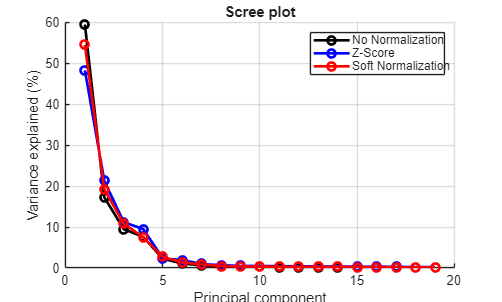

## PCA Trajectory Plots

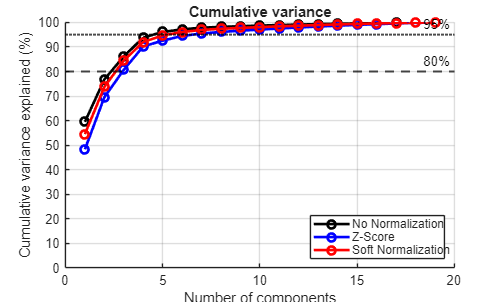

conditionIDs = [R.conditionID];
straight_idx = mod(conditionIDs, 3) == 1;
curved_idx = mod(conditionIDs, 3) == 2;
straight_trials = find(straight_idx);
curved_trials = find(curved_idx);

% window will change in the next PCA trajectory analysis this is just for
pre_window = 500;
post_window = 1500;
bin_size = 20;
time_bins = -pre_window : bin_size : post_window;
bin_centers = time_bins(1:end-1) + bin_size/2;
n_bins = numel(bin_centers);
n_units = numel(R(1).unit);


onset_align = [R.moveOnsetTime];
all_trials = [straight_trials(:); curved_trials(:)];
n_trials = numel(all_trials);

firing_rates = nan(n_trials, n_units, n_bins);
for t = 1:n_trials
    tr = all_trials(t);
    t0 = onset_align(tr);
    for u = 1:n_units
        spike_times = R(tr).unit(u).spikeTimes - t0;
        counts = histcounts(spike_times, time_bins);
        firing_rates(t, u, :) = counts / (bin_size / 1000);
    end
end
disp('Firing rates created.')

fr_straight = squeeze(mean(firing_rates(1:numel(straight_trials), :, :), 1));  % [n_units x n_bins]
fr_curved   = squeeze(mean(firing_rates(numel(straight_trials)+1:end, :, :), 1));
fr_cond_avg = permute(cat(3, fr_straight', fr_curved'), [3 1 2]);  % [2 x n_bins x n_units]
n_conds = 2;

k = 5;
soft_norm = 5;
methods = {'none', 'zscore', 'soft'};
normalization_labels = {'No Normalization', 'Z-Score', 'Soft Normalization'};
colors_method = [0 0 0; 0 0 1; 1 0 0];

n_straight = numel(straight_trials);
n_curved = numel(curved_trials);
cond_labels = [ones(n_straight, 1); 2*ones(n_curved, 1)];

fold_ids_trials = zeros(n_trials, 1);
for cond = 1:2
    cond_mask = find(cond_labels == cond);
    n_cond = numel(cond_mask);
    perm = randperm(n_cond);

Firing rates created.


    cond_folds = mod(0:n_cond-1, k) + 1;
    fold_ids_trials(cond_mask) = cond_folds(perm);
end

n_X_fixed = floor(n_units / 2);
max_dims = n_X_fixed - 1;

cv_loss = nan(numel(methods), k, k, max_dims);
n_plot_dims = min(n_X_fixed - 1, 2*n_bins - 1);
all_explained = nan(numel(methods), n_plot_dims);
all_score = cell(numel(methods), 1);
all_coeff = cell(numel(methods), 1);

for m = 1:numel(methods)

    for fold_r = 1:k
        train_idx = find(fold_ids_trials ~= fold_r);
        test_idx = find(fold_ids_trials == fold_r);
        n_train = numel(train_idx);
        n_test = numel(test_idx);

        for fold_c = 1:k
            neuron_perm = randperm(n_units);
            x_neurons = neuron_perm(1:n_X_fixed);
            y_neurons = neuron_perm(n_X_fixed+1:end);
            n_Y = numel(y_neurons);

            X_train = reshape(permute(firing_rates(train_idx, x_neurons, :), [1 3 2]), n_train*n_bins, n_X_fixed);
            Y_train = reshape(permute(firing_rates(train_idx, y_neurons, :), [1 3 2]), n_train*n_bins, n_Y);
            X_test = reshape(permute(firing_rates(test_idx,  x_neurons, :), [1 3 2]), n_test*n_bins,  n_X_fixed);
            Y_test = reshape(permute(firing_rates(test_idx,  y_neurons, :), [1 3 2]), n_test*n_bins,  n_Y);

            switch methods{m}
                case 'none'
                    X_train_n = X_train; X_test_n = X_test;
                case 'zscore'
                    mu_x = mean(X_train, 1);
                    sig_x = std(X_train, 0, 1); sig_x(sig_x==0) = 1;
                    X_train_n = (X_train - mu_x) ./ sig_x;
                    X_test_n  = (X_test  - mu_x) ./ sig_x;
                case 'soft'
                    rng_x = max(X_train,[],1) - min(X_train,[],1);
                    X_train_n = X_train ./ (rng_x + soft_norm);
                    X_test_n  = X_test  ./ (rng_x + soft_norm);
            end

            mu_X = mean(X_train_n, 1);
            X_train_c = X_train_n - mu_X;
            X_test_c = X_test_n  - mu_X;
            mu_Y = mean(Y_train, 1);
            Y_train_c = Y_train - mu_Y;

            [coeff, score, ~] = pca(X_train_c, 'NumComponents', max_dims);

            for d = 1:max_dims
                S_train = score(:, 1:d);
                beta = S_train \ Y_train_c;
                S_test = X_test_c * coeff(:, 1:d);
                Y_hat = S_test * beta + mu_Y;
                cv_loss(m, fold_r, fold_c, d) = mean((Y_test - Y_hat).^2, 'all');
            end
        end
    end

    X_plot = reshape(fr_cond_avg(:, :, :), n_conds*n_bins, n_units);
    FR_all = reshape(permute(firing_rates, [1 3 2]), n_trials*n_bins, n_units);
    
    switch methods{m}
        case 'none'
            FR_all_n = FR_all;
        case 'zscore'
            mu_x = mean(FR_all, 1);
            sig_x = std(FR_all, 0, 1); sig_x(sig_x==0) = 1;
            FR_all_n = (FR_all - mu_x) ./ sig_x;
        case 'soft'
            rng_x = max(FR_all,[],1) - min(FR_all,[],1);
            FR_all_n = FR_all ./ (rng_x + soft_norm);
    end
    
    FR_all_n = reshape(FR_all_n, n_trials, n_bins, n_units);
    psth_s = squeeze(mean(FR_all_n(1:n_straight, :, :), 1)); 
    psth_c = squeeze(mean(FR_all_n(n_straight+1:end, :, :), 1));
    X_plot_final = [psth_s; psth_c];
    X_plot_final = X_plot_final - mean(X_plot_final, 1);
    
    [coeff_full, score_full, ~, ~, explained] = pca(X_plot_final);
    all_score{m} = score_full;  
    all_explained(m, :) = explained(1:n_plot_dims)';
    all_score{m} = score_full;
    all_coeff{m} = coeff_full;
end

mean_loss = squeeze(mean(cv_loss, [2 3]));

% 2D PCA Trajectories
figure;
pc_colors = nebula(3);
for m = 1:numel(methods)
    subplot(1, 3, m); hold on;
    score = all_score{m};
    pc_straight = score(1:n_bins, cv_idx);
    pc_curved = score(n_bins+1:end, cv_idx);
    for pc = 1:3
        plot(bin_centers, score(1:n_bins, pc), '-',  'Color', pc_colors(pc,:), 'LineWidth', 2);
        plot(bin_centers, score(n_bins+1:end, pc), '--', 'Color', pc_colors(pc,:), 'LineWidth', 2);
    end
    xline(0, 'k--', 'LineWidth', 1.5);
    xlabel('Time from movement onset (ms)');
    ylabel('PC score');
    title(normalization_labels{m});
    if m == 1
        legend('PC1 straight','PC1 curved','PC2 straight','PC2 curved', ...
               'PC3 straight','PC3 curved','Location','best');
    end
end
sgtitle('Top 3 PCs Over Time');

% 3D PCA Trajectories


## Classifer

We will classify curved vs. straight reaches based on neural data from the delay and movement period separately using SVM and logistic  regression to assess when kinematic information is encoded in M1. We will assess the significance of our classifier using a Monte Carlo  shuffle test, where we shuffle curved vs straight trial labels 1000 times to generate a null distribution and compute a p-value for each method/time-window combination.

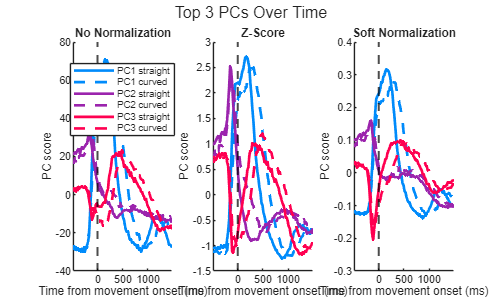

conditionIDs = [R.conditionID];
straight_idx = mod(conditionIDs, 3) == 1;
curved_idx   = mod(conditionIDs, 3) == 2;

straight_trials = find(straight_idx);
curved_trials   = find(curved_idx);
all_trials = [straight_trials(:); curved_trials(:)];
n_trials = numel(all_trials);
n_units = numel(R(1).unit);

windows.delay    = [-500, 0];
windows.movement = [0, 500];

window_labels = {'Delay Period', 'Movement Period'};
window_names  = {'delay', 'movement'};

n_windows = numel(window_labels);
bin_size = 50;

onset_align = [R.moveOnsetTime];
time_bins = windows.delay(1):bin_size:windows.movement(2);
bin_centers = time_bins(1:end-1) + bin_size/2;
n_bins = numel(bin_centers);

firing_rates = nan(n_trials, n_units, n_bins);

for t = 1:n_trials
    tr = all_trials(t);
    t0 = onset_align(tr);
    for u = 1:n_units
        spike_times = R(tr).unit(u).spikeTimes - t0;
        counts = histcounts(spike_times, time_bins);
        firing_rates(t, u, :) = counts / (bin_size / 1000);
    end
end
disp('firing rates created')

delay_bins = bin_centers >= -500 & bin_centers < 0;
movement_bins = bin_centers >= 0 & bin_centers < 500;

methods = {'svm', 'logreg'};
method_labels = {'SVM (Linear)', 'Logistic Regression'};

n_methods = numel(methods);
targetXY = reshape([R.targetXY], 2, [])';
angles = atan2d(targetXY(:,2), targetXY(:,1));
angleGroups = round(angles / 45) * 45;
angleGroups(angleGroups == 180) = -180;
uniqueGroups = unique(angleGroups);
nGroups = numel(uniqueGroups);

dir_labels_all = nan(numel(R),1);
for g = 1:nGroups
    dir_labels_all(angleGroups == uniqueGroups(g)) = g;
end

chance_level_dir = 1 / nGroups;
straight_pos = 1:numel(straight_trials);
curved_pos   = numel(straight_trials)+1 : n_trials;
barrier_conditions = { ...

firing rates created


    straight_pos, ...
    curved_pos};

for b = 1:n_barrier % sanity check to see how many trials per condition
    trial_ids = barrier_conditions{b};
    dir_labels = dir_labels_all(all_trials(trial_ids));
    fprintf('\n%s:\n', barrier_labels_str{b});
    tabulate(dir_labels)
end

barrier_labels_str = { ...
    'Straight (No Barriers)', ...
    'Curved (Barriers)'};

n_barrier = numel(barrier_conditions);
n_perm = 1000;
n_cv_folds = 5;
obs_acc_dir  = nan(n_methods, n_windows, n_barrier);
perm_acc_dir = nan(n_methods, n_windows, n_barrier, n_perm);
p_values_dir = nan(n_methods, n_windows, n_barrier);
pred_store = cell(n_methods, n_windows, n_barrier);
true_store = cell(n_methods, n_windows, n_barrier);

for b = 1:n_barrier
    trial_pos  = barrier_conditions{b};
    trial_ids  = all_trials(trial_pos); 
    dir_labels = dir_labels_all(trial_ids); 
    n_tr = numel(trial_pos);
    X_delay_b    = squeeze(mean(firing_rates(trial_pos,:,delay_bins),    3));
    X_movement_b = squeeze(mean(firing_rates(trial_pos,:,movement_bins), 3));
    window_features_b = {X_delay_b, X_movement_b};
    cv = cvpartition(dir_labels, 'KFold', n_cv_folds,'Stratify', true);



Straight (No Barriers):


  Value    Count   Percent
      1      104     13.20%
      2      133     16.88%
      3      178     22.59%
      4       61      7.74%
      5      134     17.01%
      6       83     10.53%
      7       95     12.06%



Curved (Barriers):


  Value    Count   Percent
      1      109     14.17%
      2      119     15.47%
      3      172     22.37%
      4       68      8.84%
      5      125     16.25%
      6       85     11.05%
      7       91     11.83%


    for w = 1:n_windows
        X = window_features_b{w};
        for m = 1:n_methods
            fprintf('\n========================================\n');
            fprintf('%s | %s | %s\n', ...
                method_labels{m}, ...
                window_labels{w}, ...
                barrier_labels_str{b});
            fprintf('========================================\n');
            [pred, true_lab] = classify_kfold_predictions(X, dir_labels, methods{m}, cv);
            pred_store{m,w,b} = pred;
            true_store{m,w,b} = true_lab;
            obs_acc_dir(m,w,b) = mean(pred == true_lab);
            fprintf('Observed accuracy = %.3f\n', ...
                obs_acc_dir(m,w,b));
            method_m = methods{m};
            perm_acc_tmp = nan(n_perm,1);

            parfor p = 1:n_perm
                shuf_labels = dir_labels(randperm(n_tr));
                perm_acc_tmp(p) = classify_kfold( ...
                    X, ...
                    shuf_labels, ...
                    method_m, ...
                    cv);
            end
            perm_acc_dir(m,w,b,:) = perm_acc_tmp;
            p_values_dir(m,w,b) = ...
                (sum(perm_acc_tmp >= obs_acc_dir(m,w,b)) + 1) ...
                / (n_perm + 1);

            fprintf('p-value = %.4f\n', ...
                p_values_dir(m,w,b));

        end
    end
end

fprintf('\n%s\n', repmat('-',1,75));
fprintf('%-22s %-20s %-24s %-10s %-10s\n', ...
    'Method', ...
    'Window', ...
    'Condition', ...
    'Accuracy', ...
    'p-value');
fprintf('%s\n', repmat('-',1,75));

for b = 1:n_barrier
    for w = 1:n_windows
        for m = 1:n_methods
            p_val = p_values_dir(m,w,b);
                p_str = sprintf('%.4f', p_val);

            fprintf('%-22s %-20s %-24s %-10.3f %-10s %s\n', ...
                method_labels{m}, ...
                window_labels{w}, ...
                barrier_labels_str{b}, ...
                obs_acc_dir(m,w,b), ...
                p_str, ...
                significance_label(p_val));
        end

SVM (Linear) | Delay Period | Straight (No Barriers)


Observed accuracy = 0.887


p-value = 0.0010


Logistic Regression | Delay Period | Straight (No Barriers)


Observed accuracy = 0.886


    end
end

fprintf('%s\n', repmat('-',1,75));

% Plotting
angle_strs = {'Left', 'Lower-Left', 'Lower-Right', 'Right', 'Upper-Right', 'Up', 'Upper-Left'};

for b = 1:n_barrier
    figure( ...
        'Color', 'w', ...
        'Position', [100,100,420*n_windows,380*n_methods], ...
        'Name', barrier_labels_str{b});
    panel = 0;
    for m = 1:n_methods
        for w = 1:n_windows
            panel = panel + 1;
            ax = subplot(n_methods, n_windows, panel);
            pred = pred_store{m,w,b};
            true_lab = true_store{m,w,b};
            C = zeros(nGroups, nGroups);

            for i = 1:nGroups
                for j = 1:nGroups
                    C(i,j) = sum( ...
                        true_lab == i & pred == j);
                end
            end

            C_norm = C ./ sum(C,2);
            imagesc(ax, C_norm);
            colormap(ax, 'sky');

            clim(ax, [0 1]);
            hold(ax, 'on');
            for i = 1:nGroups
                for j = 1:nGroups
                    val = C_norm(i,j);
                    txt_col = 'k';
                    if val > 0.6
                        txt_col = 'w';
                    end
                    text(ax, j, i, ...
                        sprintf('%.0f%%', val*100), ...
                        'HorizontalAlignment', 'center', ...
                        'VerticalAlignment', 'middle', ...
                        'FontSize', 8, ...
                        'Color', txt_col);
                end
            end
            for i = 1:nGroups
                rectangle(ax, ...
                    'Position', [i-0.5, i-0.5, 1, 1], ...
                    'EdgeColor', [0.9 0.5 0.1], ...
                    'LineWidth', 1.5);

            end
            p_val = p_values_dir(m,w,b);
            if p_val < 0.0001
                p_str = '< 0.0001';

            else
                p_str = sprintf('%.4f', p_val);

            end
            overall_acc = mean(pred == true_lab) * 100;

            ax.XTick = 1:nGroups;
            ax.YTick = 1:nGroups;
            ax.XTickLabel = angle_strs;
            ax.YTickLabel = angle_strs;
            ax.TickLength = [0 0];
            ax.FontSize = 9;
            xlabel(ax, 'Predicted direction');
            ylabel(ax, 'True direction');

            title(ax, sprintf( ...
                '%s | %s\nacc = %.1f%%, p = %s %s', ...
                method_labels{m}, ...
                window_labels{w}, ...
                overall_acc, ...
                p_str, ...
                significance_label(p_val)));

            cb = colorbar(ax);
            cb.Label.String = 'Proportion';
            cb.FontSize = 8;
        end
    end
    sgtitle(sprintf( ...
        'Direction Confusion Matrix — %s', ...
        barrier_labels_str{b}), ...
        'FontSize', 13, ...
        'FontWeight', 'bold');
end


Method:

## Helper functions

function ff = compute_fano_factor(counts)
    m  = mean(counts, 1);
    v  = var(counts,  0, 1);
    ff = nan(size(m));
    valid = m > 0;
    ff(valid) = v(valid) ./ m(valid);
end

function acc = classify_kfold(X, y, method, cv)
    correct = 0;
    n_folds = cv.NumTestSets;
    for fold = 1:n_folds
        train_idx = training(cv, fold);
        test_idx = test(cv, fold);

        X_train = X(train_idx,:);
        y_train = y(train_idx);

        X_test = X(test_idx,:);
        y_test = y(test_idx);

        mu = mean(X_train,1);
        sigma = std(X_train,0,1);
        sigma(sigma == 0) = 1;
        X_train = (X_train - mu) ./ sigma;
        X_test = (X_test - mu) ./ sigma;

        switch method
            case 'svm'
                t = templateSVM( ...
                    'KernelFunction', 'linear', ...
                    'Standardize', false, ...
                    'BoxConstraint', 1);
                mdl = fitcecoc( ...
                    X_train, ...
                    y_train, ...
                    'Learners', t);
            case 'logreg'
                t = templateLinear( ...
                    'Learner', 'logistic', ...
                    'Regularization', 'ridge', ...
                    'Lambda', 1/size(X_train,1));
                mdl = fitcecoc( ...
                    X_train, ...
                    y_train, ...
                    'Learners', t);
        end
        pred = predict(mdl, X_test);
        correct = correct + sum(pred == y_test);
    end
    acc = correct / numel(y);
end

function [pred_all, true_all] = classify_kfold_predictions( ...
    X, y, method, cv)
    pred_all = nan(size(y));
    true_all = y;
    n_folds = cv.NumTestSets;
    for fold = 1:n_folds
        train_idx = training(cv, fold);
        test_idx = test(cv, fold);
        X_train = X(train_idx,:);
        y_train = y(train_idx);
        X_test = X(test_idx,:);
        mu = mean(X_train,1);
        sigma = std(X_train,0,1);
        sigma(sigma == 0) = 1;
        X_train = (X_train - mu) ./ sigma;
        X_test = (X_test - mu) ./ sigma;
        switch method
            case 'svm'
                t = templateSVM( ...
                    'KernelFunction', 'linear', ...
                    'Standardize', false, ...
                    'BoxConstraint', 1);
                mdl = fitcecoc( ...
                    X_train, ...
                    y_train, ...
                    'Learners', t);
            case 'logreg'
                t = templateLinear( ...
                    'Learner', 'logistic', ...
                    'Regularization', 'ridge', ...
                    'Lambda', 1/size(X_train,1));
                mdl = fitcecoc( ...
                    X_train, ...
                    y_train, ...
                    'Learners', t);
        end
        pred_all(test_idx) = predict(mdl, X_test);
    end
end

function label = significance_label(p)
    if p < 0.001
        label = '***';
    elseif p < 0.01
        label = '**';
    elseif p < 0.05
        label = '*';
    else
        label = '(n.s.)';
    end
end
